## **One Dimensional Wave**

**Yee Algorithm**


$$S=\frac{c \Delta t}{\Delta x} = 1$$


**Parent Code: Y20201129_1**

Action => Try to fix boundary problem on right side.  Plot both H and E?  

Result => On a hunch.  I reversed the sign in the equations, which matches the derivation in the meeting notes better, and the boundary problem is now on the left. Interesting..

Admin

clearvars


sympref('FloatingPointOutput',true);

Courant number (S)

dx=1;                       

dt=1;

mu = 1;

c = 1;

epsilon = 1/(mu*c^2);

Create Matrices


S = 300;                    %Number of Space Positions
T = 125;                    %Number of Time Steps

E = zeros(1,S/dx);          %Electric
Ein = zeros(1,S/dx); 
Eout = zeros(1,S/dx); 

H = zeros (1,S/dx);         %Magnetic
Hin = zeros(1,S/dx); 
Hout = zeros (1,S/dx);      


Guassian

X=0:dx:(S/dx)-1;
a = 1;     %height
b = S/2;    %center
d = 20;    %width
f=@(x)a*exp(-((x-b).^2)/(2*d^2));
H(:)=f(X);

Square Wave

%E(50:100)=.14;

Setup Video

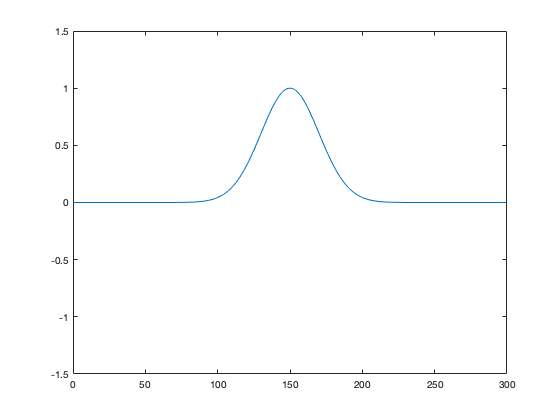

v=VideoWriter("Wave","MPEG-4");
open(v)
plot(X,H(:))
xlim([0 (S/dx)]);
ylim([-1.5 1.5]);
Ylabel="Amplitude";
Xlabel="X";
axis manual
set(gca,"nextplot","replacechildren")
frame=getframe(gcf);

writeVideo(v,frame)


Time Stepping

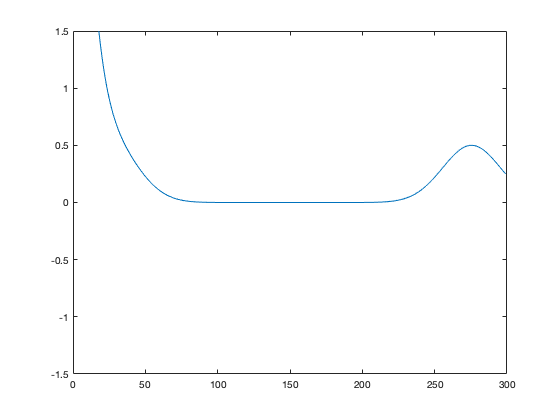


for t=1:T
    
    
    E(1) = H(2);                          % ABCs 
    E(S) = H(S);
    
    for x=2:(S-1)                     
        Hin(x)= H(x);
        Hout(x) = H(x+1);
    end   
        
    for x=2:(S-1)
       
        E(x) =  E(x) - ( dt/(epsilon*dx) ) * ( Hout(x) - Hin(x) );    %calculate E
        
    end
    
    H(1) = E(1);                          % ABCs 
    H(S) = E(S-1);
    
    for x=2:(S-1)                       
        Ein(x) = E(x-1);
        Eout(x) = E(x);
    end
    
    for x=2:(S-1)
        
        H(x) = H(x) - ( dt/(mu*dx) ) * ( Eout(x) - Ein(x) );   %calculate H
        
    end
    
    plot(X,H(:));
    frame=getframe(gcf);
    pause(0.5)
    writeVideo(v,frame)
    
end

close(v)